# 多変数関数の最小値(極値)の説明

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear
clc
close all

xを2次元で実数の変数と定義する

syms x [2 1] real

行列とベクトルを係数として与え，Jを定義する．

A=[1 0.25;0.25 1];
sympref('MatrixWithSquareBrackets',true);
(sym(A))

$$ans = \left[\begin{array}{cc} 1 & \frac{1}{4}\\ \frac{1}{4} & 1 \end{array}\right]$$

b=[3;0];
(sym(b))

$$ans = \left[\begin{array}{c} 3\\ 0 \end{array}\right]$$

c=1;
J= simplify(1/2*x'*A*x+b'*x+c)

$$J = \frac{{x_{1}}^{2}}{2}+\frac{x_{1}\,x_{2}}{4}+3\,x_{1}+\frac{{x_{2}}^{2}}{2}+1$$

x1, x2それぞれの方向の偏微分(傾き)が0となる条件を導出し，連立方程式を解く．

f(1)=diff(J,x(1))==0;
f(2)=diff(J,x(2))==0;
f

$$f = \left[\begin{array}{cc} x_{1}+\frac{x_{2}}{4}+3=0 & \frac{x_{1}}{4}+x_{2}=0 \end{array}\right]$$

xSol=solve(f)

xSol = フィールドをもつ struct :
    x1: -16/5
    x2: 4/5


minJ=subs(J,x,[xSol.x1;xSol.x2])

$$minJ = -\frac{19}{5}$$

数式を変形して求めた解と一致することを確認する．

-inv(A)*b

ans =    -3.2000
    0.8000


-1/2*b'*inv(A)*b+c

ans = -3.8000

図示する．同じ図の方向違いを複数図示する．

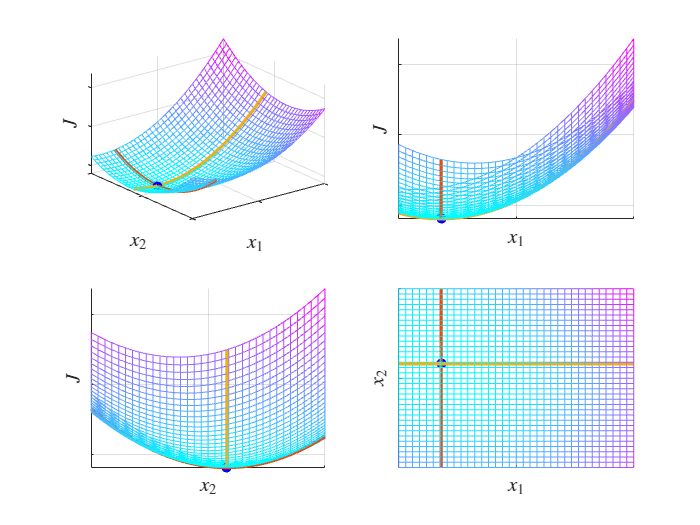

figure;
for n1=1:4
    subplot(2,2,n1)
    fsurf(J,'EdgeColor','interp','FaceAlpha',0);
    hold on;
    scatter3(xSol.x1, xSol.x2,minJ,'bo','')
    set(gca,'fontname','メイリオ');
    zticklabels([]);
    xticklabels([]);
    yticklabels([]);
    xlabel('$x_1$','Interpreter','latex','FontSize',12);
    ylabel('$x_2$','Interpreter','latex','FontSize',12);
    zlabel('$J$','Interpreter','latex','FontSize',12);
    colormap('cool')
    subs(J,x(1),xSol.x1);
    hold on;
    fplot3(xSol.x1, x(2), subs(J,x(1),xSol.x1),'LineWidth',2);
    fplot3(x(1), xSol.x2, subs(J,x(2),xSol.x2),'LineWidth',2);
    switch n1
        case 2
            view([0,0]);
        case 3
            view([90,0]);
        case 4
            view([0,90]);
    end
end

exportgraphics(gcf,'fig_minValSample01.pdf')